%  sat4_main.m
 clear; clc; close all; 

%% ---------- 0) параметры реакционных колес ----------
reaction_wheel_params4;     % создаёт: B, Bplus, tau_max, Jr, IrR_local, …

disp('B = ');

B = 


disp(B);

    0.5774    0.5774   -0.5774   -0.5774
    0.5774   -0.5774    0.5774   -0.5774
    0.5774   -0.5774   -0.5774    0.5774



fprintf('— нули в строках roll/pitch? если да – махи вообще не дают момент по этим осям.\n');

— нули в строках roll/pitch? если да – махи вообще не дают момент по этим осям.


%% 2) Небольшое смещение: поворот оси rw4 на пару градусов
angle_deg = 3; % поворот на 3°
angle_rad = deg2rad(angle_deg);
% Ось вращения: возьмём, например, произвольно [1 1 0] (нормируем)
u = [1 1 0] / norm([1 1 0]);

% Матрица поворота Rodrigues (3×3)
K = [   0, -u(3),  u(2);
      u(3),    0, -u(1);
     -u(2),  u(1),   0 ];
R = eye(3) + sin(angle_rad)*K + (1-cos(angle_rad))*K*K;

% Применяем поворот только к 4-й колонке B (rw4)
B_pert = B;
B_pert(:,4) = R * B(:,4)

B_pert =     0.5774    0.5774   -0.5774   -0.5560
    0.5774   -0.5774    0.5774   -0.5987
    0.5774   -0.5774   -0.5774    0.5766


% затем заново нормируем все колонки (вдруг чуть ушли по длине)
for i = 1:4
    B_pert(:,i) = B_pert(:,i) / norm(B_pert(:,i));
end
disp(B_pert);

    0.5774    0.5774   -0.5774   -0.5560
    0.5774   -0.5774    0.5774   -0.5987
    0.5774   -0.5774   -0.5774    0.5766




%%% ---------- 1) параметры КА (корпус + 4 колеса) ----------
ms = 2.6;                    % масса КА, кг
lx = 0.10; ly = 0.10; lz = 0.20;   % габариты, м

Is = (ms/12) * diag([ly^2+lz^2, lx^2+lz^2, lx^2+ly^2]);  % корпус
I  = Is + 4*IrR_local;        % + 4 одинаковых колеса, грубо
invI = inv(I);
disp('Is ='); disp(Is);

Is =
    0.0108         0         0
         0    0.0108         0
         0         0    0.0043



disp('I ='); disp(I);

I =
    0.0113         0         0
         0    0.0111         0
         0         0    0.0046



s = svd(B);
sigma_min = s(end);
M_test = [5e-3;0;0];

%% ---------- 2) начальное состояние ----------
omega0     = deg2rad([ 0;  0; 0]);   % рад/с
% omega0     = [ 0.5; 0; 0; ];   % рад/с
q0         = [1; 0; 0; 0];            % без поворота
omega_rw0  = zeros(4,1);              % скорости колес
x0 = [omega0; q0; omega_rw0];         % 3+4+4 = 11×1


%% ---------- 3) регулятор и целевая ориентация ----------
Ix = I(1,1);  Iy = I(2,2);  Iz = I(3,3);

% требования
Ts = 50;      % с
zeta = 0.8;

wn = 4 / (zeta * Ts);     % общая частота

% коэффициенты
Kp_x = Ix * wn^2;
Kd_x = 2 * zeta * wn * Ix;

Kp_y = Iy * wn^2;
Kd_y = 2 * zeta * wn * Iy;

Kp_z = Iz * wn^2;
Kd_z = 2 * zeta * wn * Iz;

 Kp = diag([Kp_x, Kp_y, Kp_z]);
 Kd = diag([Kd_x, Kd_y, Kd_z]);
%   Kp = diag([0.05 0.05 0.05]);
%   Kd = diag([0.3 0.3 0.3]);



eul = deg2rad([0,0,50]);
q_des = eul2quat(eul,'ZYX').';   % вернёт 1×4, транспонируем в 4×1

M_dist = [0;0;0;];                   % возмущающий момент, Н·м
use_tikh = 0; 
pars.lambda = 0;
pars.fail_idx = [];  % индекс маховика, выходящего из строя
pars.t_fail  = [0]; % время отказа
pars.I       = I;
pars.invI    = invI;
pars.Kp      = Kp;
pars.Kd      = Kd;
pars.q_des   = q_des;
pars.B       = B;                     % 3×4
pars.Bplus   = Bplus;                 % 4×3
pars.tau_max = tau_max;
pars.Jr      = Jr;                    % скаляр
pars.M_dist  = M_dist;
pars.omega_lim = 600;
if use_tikh
pars.alloc      = @(T) ridge_alloc(T, pars.B,      pars.lambda);
pars.alloc_free = @(T,Bf) ridge_alloc(T, Bf,        pars.lambda);
else
    pars.alloc = @(T) pinv(pars.B) * T;
    pars.alloc_free = @(T,Bf) pinv(Bf)*T;
end

%% ---------- 6) интегрирование ODE ----------
tspan = [0 500];
opts  = odeset('MaxStep', 0.1);

global log_tau log_t idx log_omega_s
idx = []; log_tau = []; log_t = []; log_omega_s = [];
[t, x] = ode45(@(t,x) rhs_attitude4(t, x, pars), tspan, x0, opts);

Time = 0.00 s
Time = 5.03 s
Time = 10.04 s
Time = 15.05 s
Time = 20.05 s
Time = 25.05 s
Time = 30.05 s
Time = 35.05 s
Time = 40.05 s
Time = 45.05 s
Time = 50.05 s
Time = 55.05 s
Time = 60.06 s
Time = 65.06 s
Time = 70.06 s
Time = 75.07 s
Time = 80.07 s
Time = 85.10 s
Time = 90.10 s
Time = 95.10 s
Time = 100.11 s
Time = 105.11 s
Time = 110.11 s
Time = 115.11 s
Time = 120.11 s
Time = 125.11 s
Time = 130.11 s
Time = 135.12 s
Time = 140.12 s
Time = 145.12 s
Time = 150.12 s
Time = 155.13 s
Time = 160.13 s
Time = 165.13 s
Time = 170.14 s
Time = 175.14 s
Time = 180.14 s
Time = 185.14 s
Time = 190.15 s
Time = 195.15 s
Time = 200.15 s
Time = 205.15 s
Time = 210.15 s
Time = 215.16 s
Time = 220.16 s
Time = 225.16 s
Time = 230.16 s
Time = 235.17 s
Time = 240.17 s
Time = 245.17 s
Time = 250.17 s
Time = 255.17 s
Time = 260.17 s
Time = 265.18 s
Time = 270.18 s
Time = 275.18 s
Time = 280.18 s
Time = 285.18 s
Time = 290.19 s
Time = 295.19 s
Time = 300.19 s
Time = 305.19 s
Time = 310.19 s
Time = 315.19 

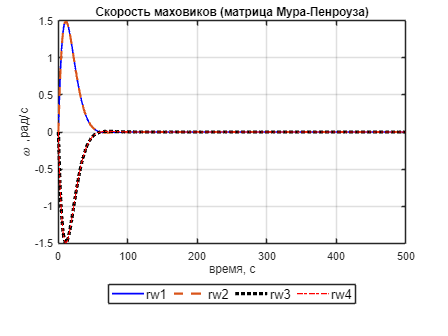

omega_rw = x(:,8:11);

figure;
h = plot(t,omega_rw);
legend('rw1','rw2','rw3','rw4','Location','southoutside', ...
       'Orientation','horizontal','FontSize', 12); xlabel('время, с'); ylabel('\omega ,рад/с'); grid on;
title("Скорость маховиков (матрица Мура-Пенроуза)")
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % r1
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % r2
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % r3
set(h(4), 'LineStyle','-.', 'LineWidth',1,   'Color','r');    % r4

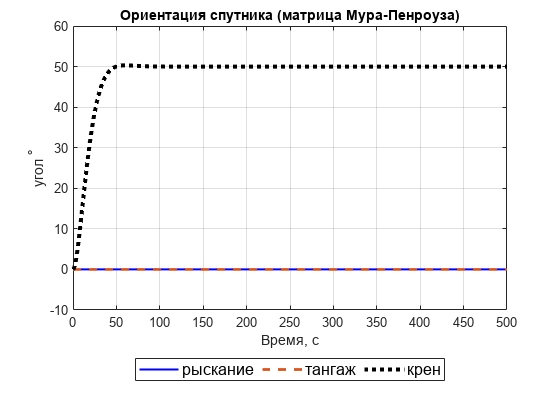

q = x(:,4:7);
q = q./vecnorm(q,2,2);
euler = zeros(length(t),3);
% --- кватернионы -> углы Эйлера (градусы) ---
euler_deg = zeros(length(t),3);
for k = 1:length(t)
    R = quat2rotm(q(k,:));
    euler_deg(k,:) = rad2deg( rotm2eul(R,'ZYX') );
end
% --- делаем непрерывными и возвращаем в градусы ---
euler_cont = rad2deg( unwrap( deg2rad(euler_deg), [], 1) );  % 3 столбца

figure;
h = plot(t, euler_cont.');      % 3×N  (правильное имя!)
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % yaw
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % pitch
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % roll
legend({'рыскание','тангаж','крен'}, ...
       'Location','southoutside', ...
       'Orientation','horizontal','FontSize', 12);
 xlabel('Время, с','FontSize', 11); ylabel('угол ^\circ','FontSize', 11);
 title("Ориентация спутника (матрица Мура-Пенроуза)")
grid on

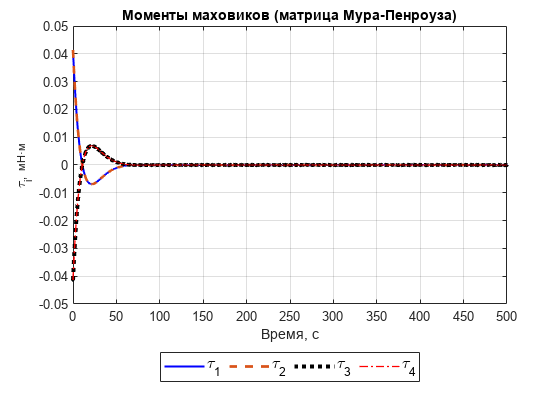


tau_x = log_tau;
k = idx-1;                        % фактическое число записей
figure; 
h = plot(log_t(1:k), 1e3*tau_x(:,1:k).');
xlabel('Время, с');  ylabel('\tau_i,  мН·м');
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % tau1
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % tau2
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % tau3
set(h(4), 'LineStyle','-.', 'LineWidth',1,   'Color','r');    % tau4
title("Моменты маховиков (матрица Мура-Пенроуза)")
legend('\tau_1','\tau_2','\tau_3','\tau_4','Location','southoutside', 'Orientation','horizontal','FontSize', 12);
grid on;



idx = []; log_tau = []; log_t = []; log_omega_s = [];
use_tikh = 1; 
pars.lambda = 0.5;
pars.alloc      = @(T) ridge_alloc(T, pars.B,      pars.lambda);
pars.alloc_free = @(T,Bf) ridge_alloc(T, Bf,        pars.lambda);
[tt, xx] = ode45(@(t,x) rhs_attitude4(t, x, pars), tspan, x0, opts);

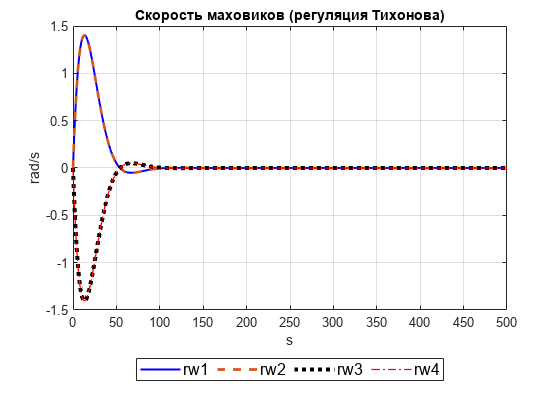


omega_rw_xx = xx(:,8:11);

figure;
h = plot(tt,omega_rw_xx);
legend('rw1','rw2','rw3','rw4','Location','southoutside', ...
       'Orientation','horizontal','FontSize', 12); xlabel('s'); ylabel('rad/s'); grid on;
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % r1
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % r2
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % r3
set(h(4), 'LineStyle','-.', 'LineWidth',1,   'Color','r');    % r4
title("Скорость маховиков (регуляция Тихонова)")

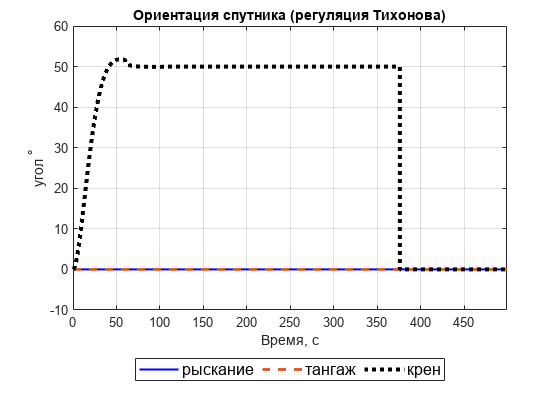

q = xx(:,4:7);
q = q./vecnorm(q,2,2);
euler = zeros(length(t),3);
% --- кватернионы -> углы Эйлера (градусы) ---
euler_deg = zeros(length(t),3);
for k = 1:length(tt)
    R = quat2rotm(q(k,:));
    euler_deg(k,:) = rad2deg( rotm2eul(R,'ZYX') );
end
% --- делаем непрерывными и возвращаем в градусы ---
euler_cont = rad2deg( unwrap( deg2rad(euler_deg), [], 1) );  % 3 столбца

figure;
h = plot(t, euler_cont.');      % 3×N  (правильное имя!)
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % yaw
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % pitch
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % roll
legend({'рыскание','тангаж','крен'}, ...
       'Location','southoutside', ...
       'Orientation','horizontal','FontSize', 12);
title("Ориентация спутника (регуляция Тихонова)")
 xlabel('Время, с','FontSize', 11); ylabel('угол ^\circ','FontSize', 11);
grid on
xlim([0 499])

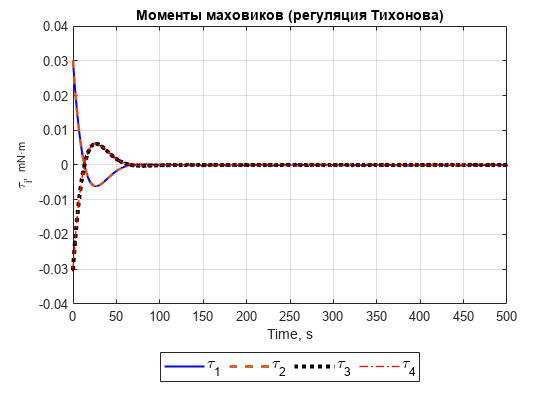


tau_xx = log_tau;
k = idx-1;                        % фактическое число записей
figure; 
h = plot(log_t(1:k), 1e3*tau_xx(:,1:k).');
xlabel('Time, s');  ylabel('\tau_i,  mN·m');
set(h(1), 'LineStyle','-',  'LineWidth',1.5, 'Color','b');   % tau1
set(h(2), 'LineStyle','--', 'LineWidth',2,   'Color',[0.85 0.33 0.1]); % tau2
set(h(3), 'LineStyle',':', 'LineWidth',3,   'Color','k');    % tau3
set(h(4), 'LineStyle','-.', 'LineWidth',1,   'Color','r');    % tau4
title("Моменты маховиков (регуляция Тихонова)")
legend('\tau_1','\tau_2','\tau_3','\tau_4','Location','southoutside', 'Orientation','horizontal','FontSize', 12);
grid on;